# Explore the Challenge Dataset 

Table of contents

- Enroll Data

- Test Data

- Mandated Trials

- Additional "Samples" data folder

- Samples folder - Retrieve Speaker and ROI labels

- Samples folder - inspect and playback individual channels

- Samples folder - Process and use ROI labels

- Create a few different datastores to help get data of interest

Use this to store the root location of the dataset

dataloc = "E:\SP CUP\sasika\ROBOVOX_SP_CUP_2024";
cd(dataloc)

## Enroll data

The essential data to use for the challenge is included within the "single-channel" subfolder

singleChLoc = fullfile(dataloc, "data", "single-channel");

Let's look at the dimensions of the enrollment data first

enrollloc = fullfile(singleChLoc, "enrollment")

enrollloc = "E:\SP CUP\sasika\ROBOVOX_SP_CUP_2024\data\single-channel\enrollment"

The speaker tag is included in the name of the audio recording files, as the string that precede the first "-"

spk_labels_enroll = filenames2labels(enrollloc, ExtractBefore="-", FileExtensions=".wav")

spk_labels_enroll = 225×1 categorical array
     spk_10 
     spk_10 
     spk_10 
     spk_11 
     spk_11 
     spk_11 
     spk_12 
     spk_12 
     spk_12 
     spk_13 
     spk_13 
     spk_13 
     spk_14 
     spk_14 
     spk_14 
     spk_15 
     spk_15 
     spk_15 
     spk_16 
     spk_16 
     spk_16 
     spk_17 
     spk_17 
     spk_17 
     spk_18 
     spk_18 
     spk_18 
     spk_19 
     spk_19 
     spk_19 


spk_ids = unique(spk_labels_enroll)

spk_ids = 75×1 categorical array
     spk_10 
     spk_11 
     spk_12 
     spk_13 
     spk_14 
     spk_15 
     spk_16 
     spk_17 
     spk_18 
     spk_19 
     spk_2 
     spk_20 
     spk_21 
     spk_22 
     spk_23 
     spk_24 
     spk_25 
     spk_26 
     spk_27 
     spk_28 
     spk_29 
     spk_3 
     spk_30 
     spk_31 
     spk_32 
     spk_33 
     spk_34 
     spk_35 
     spk_36 
     spk_37 


numSpk = height(spk_ids)

numSpk = 75

How many enrollment files per speaker?

numfiles_enroll = zeros(numSpk, 1);
for kSpk = 1:numSpk
    numfiles_enroll(kSpk) = sum(double(spk_labels_enroll == spk_ids(kSpk)));
end 
spkFileCount_enroll = table(spk_ids, numfiles_enroll)

spkFileCount_enroll = 75×2 table
    spk_ids    numfiles_enroll
    _______    _______________

    spk_10            3       
    spk_11            3       
    spk_12            3       
    spk_13            3       
    spk_14            3       
    spk_15            3       
    spk_16            3       
    spk_17            3       
    spk_18            3       
    spk_19            3       
    spk_2             3       
    spk_20            3       
    spk_21            3       
    spk_22            3       
    spk_23            3       
    spk_24            3       


Read a few samples.

Create a "datastore" object first. Use datastores to: 

- Read dataset files sequentially, without having to specify individual filenames.

- Pair files and labels(other menthods also available)

- Pass collections of files to AI models of other built-in functions

- Summarize statistics around dataset

ads_enr = audioDatastore(enrollloc);
ads_enr.Labels = spk_labels_enroll

ads_enr =   audioDatastore with properties:

                       Files: {
                              ' ...\data\single-channel\enrollment\spk_10-10_21_0_0_d2_ch5.wav';
                              ' ...\data\single-channel\enrollment\spk_10-10_21_0_0_d3_ch5.wav';
                              ' ...\data\single-channel\enrollment\spk_10-10_21_0_0_d4_ch5.wav'
                               ... and 222 more
                              }
                     Folders: {
                              'E:\SP CUP\sasika\ROBOVOX_SP_CUP_2024\data\single-channel\enrollment'
                              }
                      Labels: [spk_10; spk_10; spk_10 ... and 222 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


countEachLabel(ads_enr)

ans = 75×2 table
    Label     Count
    ______    _____

    spk_10      3  
    spk_11      3  
    spk_12      3  
    spk_13      3  
    spk_14      3  
    spk_15      3  
    spk_16      3  
    spk_17      3  
    spk_18      3  
    spk_19      3  
    spk_2       3  
    spk_20      3  
    spk_21      3  
    spk_22      3  
    spk_23      3  
    spk_24      3  


shuffle(ads_enr)

ans =   audioDatastore with properties:

                       Files: {
                              ' ...\data\single-channel\enrollment\spk_47-47_12_0_0_d4_ch5.wav';
                              ' ...\data\single-channel\enrollment\spk_4-4_10_0_0_d5_ch5.wav';
                              ' ...\data\single-channel\enrollment\spk_62-62_11_0_0_d2_ch5.wav'
                               ... and 222 more
                              }
                     Folders: {
                              'E:\SP CUP\sasika\ROBOVOX_SP_CUP_2024\data\single-channel\enrollment'
                              }
                      Labels: [spk_47; spk_4; spk_62 ... and 222 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


Listen to and inspect a few randomly sampled files

[x, xinfo] = read(ads_enr) 

x =    -0.0074
   -0.0062
   -0.0047
   -0.0040
    0.0027
    0.0070
    0.0036
   -0.0014
    0.0019
    0.0053


xinfo = struct with fields:
    SampleRate: 16000
      FileName: 'E:\SP CUP\sasika\ROBOVOX_SP_CUP_2024\data\single-channel\enrollment\spk_10-10_21_0_0_d2_ch5.wav'
         Label: spk_10


filenames2labels(xinfo.FileName, FileExtensions=".wav")

ans = categorical
     spk_10-10_21_0_0_d2_ch5 


soundsc(x, xinfo.SampleRate)

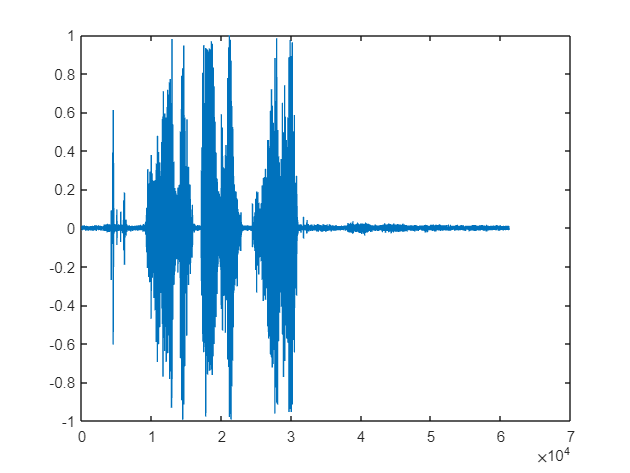

sampleClippedEnrollmentFile = "spk_10-10_21_0_0_d2_ch5.wav"; 
%sampleClippedEnrollmentFile = "spk_12-12_10_0_0_d6_ch5.wav" % woman
% sampleClippedEnrollmentFile = "spk_14-14_21_1_0_d1_ch5.wav"; % man
[x,fs] = audioread(fullfile(enrollloc, sampleClippedEnrollmentFile));
plot(x)

Note : ***(what does this mean here?)***

- ***Important amplitude clipping ***

- ***Fairly "generous" segmentation***

- ***High noise floor***

soundsc(x, fs)

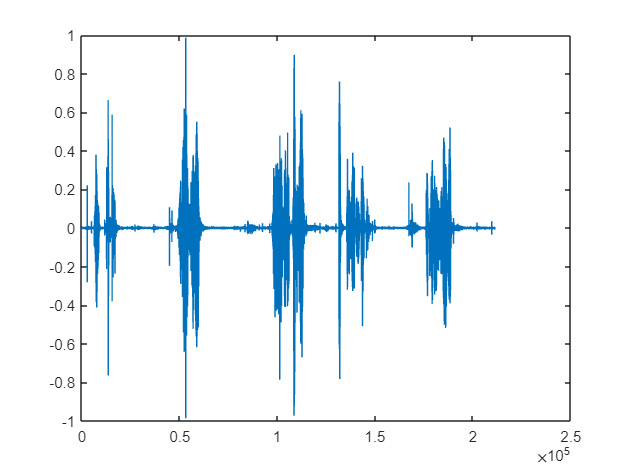

sampleNonsegmentedEnrollmentFile = "spk_15-15_19_0_1_d6_ch5.wav";
[x,fs] = audioread(fullfile(enrollloc, sampleNonsegmentedEnrollmentFile));
plot(x)

soundsc(x,fs)

## Test data

testLoc = fullfile(singleChLoc, "test");
ads_test = audioDatastore(testLoc)

ads_test =   audioDatastore with properties:

                       Files: {
                              ' ...\sasika\ROBOVOX_SP_CUP_2024\data\single-channel\test\0000f88619.wav';
                              ' ...\sasika\ROBOVOX_SP_CUP_2024\data\single-channel\test\000f6d0072.wav';
                              ' ...\sasika\ROBOVOX_SP_CUP_2024\data\single-channel\test\001dd0cb47.wav'
                               ... and 10329 more
                              }
                     Folders: {
                              'E:\SP CUP\sasika\ROBOVOX_SP_CUP_2024\data\single-channel\test'
                              }
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
                      Labels: {}
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


numTestFiles = length(ads_test.Files)

numTestFiles = 10332

shuffle(ads_test)

ans =   audioDatastore with properties:

                       Files: {
                              ' ...\sasika\ROBOVOX_SP_CUP_2024\data\single-channel\test\e1b7d75527.wav';
                              ' ...\sasika\ROBOVOX_SP_CUP_2024\data\single-channel\test\c4e70222f6.wav';
                              ' ...\sasika\ROBOVOX_SP_CUP_2024\data\single-channel\test\64a5bf53c4.wav'
                               ... and 10329 more
                              }
                     Folders: {
                              'E:\SP CUP\sasika\ROBOVOX_SP_CUP_2024\data\single-channel\test'
                              }
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
                      Labels: {}
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


Inspect and listen to test samples

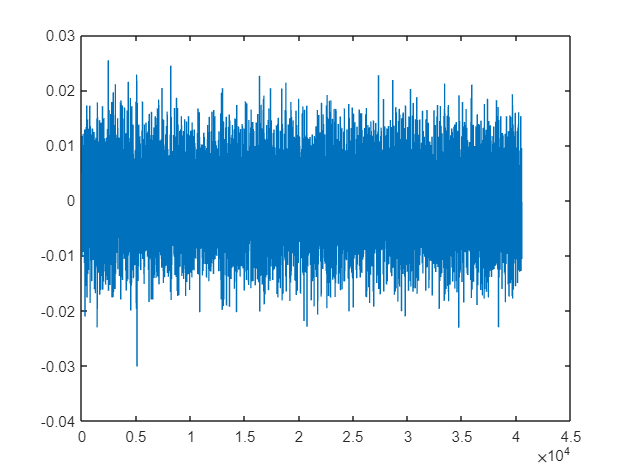

[x, xinfo] = read(ads_test);
plot(x)

xinfo

xinfo = struct with fields:
    SampleRate: 16000
      FileName: 'E:\SP CUP\sasika\ROBOVOX_SP_CUP_2024\data\single-channel\test\0000f88619.wav'


filenames2labels(xinfo.FileName,FileExtensions=".wav")

ans = categorical
     0000f88619 


soundsc(x, xinfo.SampleRate)

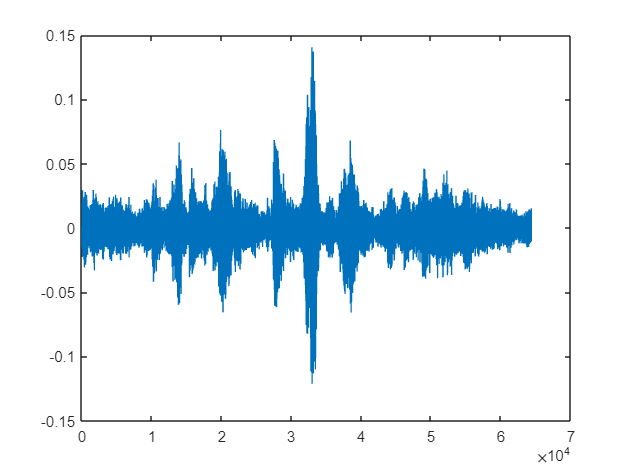

% sampleTestFile = "0000f88619.wav"; % Noise only?
% sampleTestFile = "00465a38b0.wav"; % More than one  target speaker
 sampleTestFile = "006a19dfc1.wav"; % More than one target speaker
[x, fs] = audioread(fullfile(testLoc, sampleTestFile));
plot(x)

soundsc(x, fs)

NOTE : 

- Even higher noise floor

- Significant reverberation

- Additional possible challenges  such as

- There can be more than one speaker( but there's a prominent one)

- There can be no speaker too.

## Mandated trials

Inpsect trials file

trialsFilename = "signle-channel-trials.trl";
open(fullfile(singleChLoc, trialsFilename))

Import pairs into table

trialsTable = readtable(fullfile(singleChLoc, trialsFilename), ...
    FileType="text", Delimiter=" ", ReadRowNames=false, ReadVariableNames=false)

trialsTable = 102558×1 table
             Var1         
    ______________________

    {'spk_71→b80bb95d16'}
    {'spk_71→e64da37b33'}
    {'spk_71→c22d8f9d8a'}
    {'spk_71→20e087d5bf'}
    {'spk_71→c5396d4af7'}
    {'spk_71→07e622c018'}
    {'spk_71→70d3397783'}
    {'spk_71→e967199344'}
    {'spk_71→35e670b698'}
    {'spk_71→6d80d0d2a1'}
    {'spk_71→97bbaeadba'}
    {'spk_71→a62faf1119'}
    {'spk_71→34ceda1014'}
    {'spk_71→33e5a6f028'}
    {'spk_71→bf3c182f9a'}
    {'spk_71→e350f7e8d3'}


***The Problem statement : What's the probability that the voice recording belongs to the corresponding speaker?***

How many trials requested for scoring?

numTrials = height(trialsTable)

numTrials = 102558

How many possible trials are there? 

numPossiblePairs = numSpk * numTestFiles

numPossiblePairs = 774900

How many trials per speaker?

numfiles = zeros(numSpk, 1);
for kSpk = 1:numSpk
    numfiles(kSpk) = sum(categorical(trialsTable.Var1) == spk_ids(kSpk));
end 
spkFileCount = table(spk_ids, numfiles)

spkFileCount = 75×2 table
    spk_ids    numfiles
    _______    ________

    spk_10        0    
    spk_11        0    
    spk_12        0    
    spk_13        0    
    spk_14        0    
    spk_15        0    
    spk_16        0    
    spk_17        0    
    spk_18        0    
    spk_19        0    
    spk_2         0    
    spk_20        0    
    spk_21        0    
    spk_22        0    
    spk_23        0    
    spk_24        0    


## Additional "Samples" data folder

********Why this "samples" folder for?***

locraw = fullfile(dataloc, "data" , "samples");
rawds = audioDatastore(locraw, "IncludeSubfolders", true)

rawds =   audioDatastore with properties:

                       Files: {
                              'E:\SP CUP\sasika\ROBOVOX_SP_CUP_2024\data\samples\1_1_0_1\sound.wav';
                              'E:\SP CUP\sasika\ROBOVOX_SP_CUP_2024\data\samples\1_1_1_0\sound.wav';
                              'E:\SP CUP\sasika\ROBOVOX_SP_CUP_2024\data\samples\1_22_0_0\sound.wav'
                               ... and 35 more
                              }
                     Folders: {
                              'E:\SP CUP\sasika\ROBOVOX_SP_CUP_2024\data\samples'
                              }
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
                      Labels: {}
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


Inspect one sample

[xs, xsinfo] = read(rawds)

xs =          0         0         0         0         0         0         0         0
   -0.0000    0.0000         0    0.0001         0    0.0000         0         0
    0.0000   -0.0000         0   -0.0000         0         0         0         0
    0.0001         0         0   -0.0002         0   -0.0001   -0.0000   -0.0000
   -0.0003    0.0001         0    0.0008    0.0001    0.0003    0.0001    0.0001
    0.0007   -0.0003         0   -0.0017   -0.0001   -0.0007   -0.0002   -0.0002
   -0.0012    0.0008    0.0001    0.0029    0.0002    0.0012    0.0004    0.0003
    0.0018   -0.0014   -0.0001   -0.0041   -0.0002   -0.0017   -0.0006   -0.0005
   -0.0032    0.0033    0.0004    0.0069    0.0001    0.0030    0.0011    0.0009
   -0.0251    0.0158    0.0036    0.0685    0.0031    0.0275    0.0097    0.0079


xsinfo = struct with fields:
    SampleRate: 16000
      FileName: 'E:\SP CUP\sasika\ROBOVOX_SP_CUP_2024\data\samples\1_1_0_1\sound.wav'


numch = size(xs, 2);

tl = tiledlayout("vertical")

Error using tiledlayout
Invalid arguments.

for kc = 1:numch
    nexttile
    % plot(x(:,kc))
    audioEnveolpe(xs(:,kc), SampleRate=info.SampleRate)
end 
tl.TileSpacing = "none";
tl.Padding = "tight";

## There's an error here when plotting. 

## Samples Folder - Retrieve Speaker and ROI labels

The Speaker ID are easy to get through the folder names

rawlabs = folders2labels(rawds);
spkrlabs = extractBefore(string(rawlabs), "_");

Store anything following the speaker ID in a separate "Run" vairable

rublabs = extractAfter(string(rawlabs), "_");

Get ROI - Parse file "annotations.txt" for each recording and store the ROI data in a separate ROI table

Note : start and stop times define regions where the ***robot (not the human speaker)*** is talking

numruns = height(rawlabs);
roi = cell(numruns,1);
for krun = 1:numruns
    filename = fullfile(locraw, string(rawlabs(krun)), 'annotations.txt');
    t = readtable(filename, ReadVariableNames=false, ReadRowNames=true);
    t.Properties.VariableNames = ["start", "stop"];
    roi{krun} = t;
end

Example of imported ROI labels for a single multi-channel recording

t

t = 7×2 table
                 start       stop 
                ________    ______

    noise       0.009348    3.0124
    greeting      3.0184    5.1663
    0             7.8933    10.344
    1             12.895    14.792
    2             17.522    19.866
    3             21.805    24.503
    4             27.811    30.347


Collate all labels into a table.

anno = table(spkrlabs, rublabs, roi);
anno.Properties.VariableNames = ["Speaker","Run","ROI"];
rawds.Labels = anno;

## Samples Folder - inspect and playback individual channels

[x, info] = read(rawds);
fs = info.SampleRate;

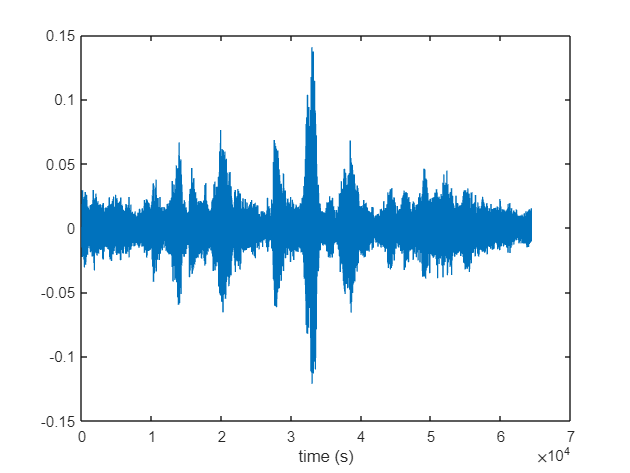

probeChannel = 5;
y = x(:, probeChannel);
t = (1/fs) * (0:length(y)-1)';

xlabel("time (s)");

soundsc(x(:,probeChannel), info.SampleRate);
numch = size(x,2);
% stackedplot(x)
tl = tiledlayout("vertical");

Error using tiledlayout
Invalid arguments.

## Sample Folder - Process and use ROI labels

The original ROI table identify two initial regions commons to all recordings, and a few start+stop "regions of interest" corresponding to the robot questions

roiTime = info.Label.ROI{1}

roiTime = 7×2 table
                 start       stop 
                ________    ______

    noise       0.008159    3.0112
    greeting      3.0269     5.894
    0             8.5773    10.772
    1             13.605    16.146
    2             18.391    21.551
    3             25.699    28.243
    4             30.714    33.279


roiSamples = round(info.SampleRate * roiTime{:,:})

roiSamples =          131       48180
       48430       94305
      137237      172358
      217682      258338
      294254      344817
      411182      451885
      491422      532470


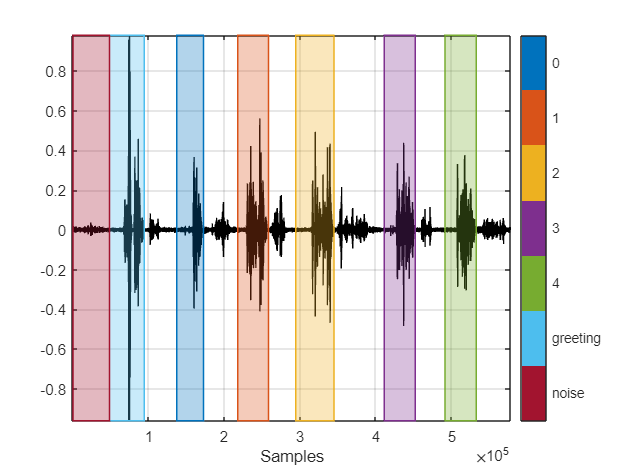

mask = sigroi2binmask(roiSamples);
% sigmask = signalMask(table(roiSamples(2:end,:), repmat("tobot", height(roiSamples)-1,1)));
sigmask = signalMask(table(roiSamples(1:end,:), string(roiTime.Properties.RowNames)));
figure
plotsigroi(sigmask, x(:,4), true)

Construct an ROI table identifying the **speaker responses**

auinfo = audioinfo(info.FileName);
spkRoi = [roiSamples(2:end-1,2),roiSamples(3:end,1);...
    roiSamples(end,2), auinfo.TotalSamples]

spkRoi =        94305      137237
      172358      217682
      258338      294254
      344817      411182
      451885      491422
      532470      577536


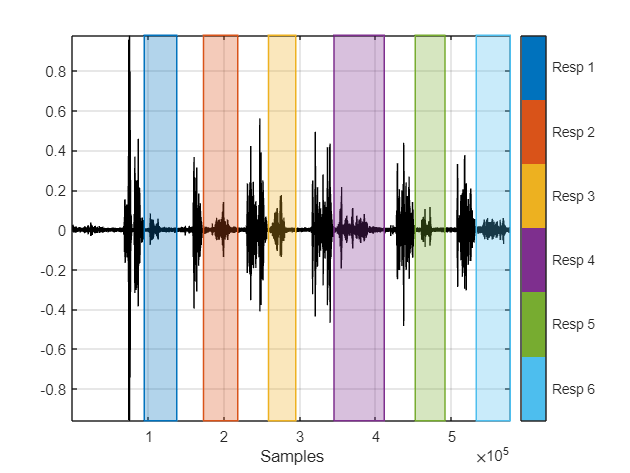

sigmask = signalMask(table(spkRoi,string("Resp " + string(1:height(spkRoi))')));
plotsigroi(sigmask, x(:,4), true) 

Y = extractsigroi(y, spkRoi, false)

Y = 6×1 cell array
    {42933×1 double}
    {45325×1 double}
    {35917×1 double}
    {66366×1 double}
    {39538×1 double}
    {45067×1 double}


probeSegment = 1

probeSegment = 1

soundsc(Y{probeSegment},fs);

## Create a few different datastores to help get data of interest 

Transform datastore to only labeled as "noise" in each recording (initial segment)

noiseds = transform(rawds, @getSampleNoise, IncludeInfo=true);

Error using nargin
Function getSampleNoise does not exist.

Error in matlab.io.datastore.TransformedDatastore (line 156)
                    tFuncArgs = nargin(fun);

Error in matlab.io.datastore.internal.buildTransforme

Transform datastore to get robot greeting for each segment - not overly useful, just proof of concept

greetds = transform(rawds, @getSampleGreeting, IncludeInfo=true);

Transform datastore to get individual ordered segments of speaker responses **(only channels 4 and 5!)**

seg3ds = transform(rawds, @getSampleSegment3, IncludeInfo=true);
seg5ds = transform(rawds, @getSampleSegment5, IncludeInfo=true);

Transform datastore to get **all **ordered segments of speaker responses **(only channels 4 and 5!) **- the output is a cell array where each cell is a multi-channel segment responses

segsds = transform(rawds, @getSamplSegments, IncludeInfo=true);
[x, info] = read(segsds);

Example : get a random noise samples for channel 5 (enrollment channel) 

shuffle(noiseds);

[n, ninfo] = read(noiseds);
size(n)

% Channel 1 -> channel 4
% Channel 2 -> channel 5
soundsc(n(:,1),fs)